Problema 2

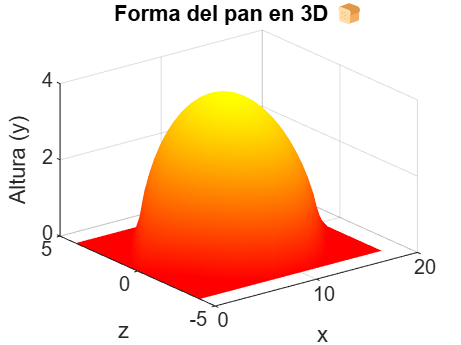

clc; clear; close all;

% --- Función de altura
f = @(x, z) sqrt((4 * sin(pi * x / 18)).^2 - z.^2);
g = @(x, z) ((4 * sin(pi * x / 18)).^2 - z.^2) >= 0; % Dominio válido

% --- Rango y mallas
x = 0:0.5:18;
z = -4:0.25:4;
[X, Z] = meshgrid(x, z);

% --- Evaluar f en malla
Y = f(X, Z);
Y(~g(X, Z)) = 0;  % Anular valores fuera del dominio válido

% --- Gráfica 3D (sin transponer nada)
surf(X, Z, Y)
xlabel('x'); ylabel('z'); zlabel('Altura (y)')
title('Forma del pan en 3D 🍞')
shading interp
colormap autumn


% --- Regla compuesta de Simpson 1/3 doble
hx = 0.5;
hz = 0.25;

[nz, nx] = size(Y);
if mod(nx-1, 2) ~= 0 || mod(nz-1, 2) ~= 0
    error('Debe haber un número par de subintervalos (nx-1 y nz-1 deben ser pares)');
end

% Simpson 1/3 doble
S = 0;
for i = 1:2:nz-2
    for j = 1:2:nx-2
        local = Y(i,j) + 4*Y(i+1,j) + Y(i+2,j) + ...
                4*Y(i,j+1) + 16*Y(i+1,j+1) + 4*Y(i+2,j+1) + ...
                Y(i,j+2) + 4*Y(i+1,j+2) + Y(i+2,j+2);
        S = S + local;
    end
end
V_simpson = (hx * hz / 9) * S;

% --- Valor "exacto" con integral2
fint = @(x,z) sqrt((4*sin(pi*x/18)).^2 - z.^2);
V_exacto = integral2(fint, 0, 18, @(x)-4*sin(pi*x/18), @(x)4*sin(pi*x/18));

% --- Error relativo verdadero
error = abs((V_simpson - V_exacto) / V_exacto);

% --- Resultados
fprintf("Volumen estimado con Simpson: %.6f cm³\n", V_simpson);

Volumen estimado con Simpson: 226.391505 cm³


fprintf("Volumen exacto (integral2):   %.6f cm³\n", V_exacto);

Volumen exacto (integral2):   226.194671 cm³


fprintf("Error relativo verdadero:     %.6f %%\n", error * 100);

Error relativo verdadero:     0.087020 %
